# **扭摆法测定物体转动惯量**

## **测定物体的转动惯量**

format long
%读取周期，并算出平均值
T_10 = load('t_1.txt');T_ave = sum(T_10,2)./30;
%读取金属圆筒尺寸，算出平均值（1行：外径，2行：内径）
D_J = load('金属圆筒尺寸.txt')*0.001;D_J_ave = sum(D_J,2)./3;
D_s = load('塑料圆筒尺寸.txt')*0.001;D_1 = sum(D_s,2)./3;
M = load('kg.txt');
L = load('金属细杆尺寸.txt')*0.001;

T_0 = T_ave(1,:);
T_1 = T_ave(2,:);
T_12 = T_ave(2:3,:);
T_4 = T_ave(4);

I_t1 = (1/8)*M(1)*D_1^2;
K = 4*pi^2*I_t1/(T_1^2 - T_0^2);
I_t2 = (1/8) * M(2) *(D_J_ave(1)^2 + D_J_ave(2)^2);
I_t4 = (1/12) * M(3) * L^2;
I_t = [I_t1;I_t2;I_t4];

I_0 = (I_t1 * T_0^2)/(T_1 ^ 2 - T_0 ^2);
I_12 = (K * T_12 .^ 2)/(4*pi^2)-[I_0;I_0];
I_4 = K*T_4^2/(4*pi^2);
I_r = [I_12;I_4];

cent =  abs(I_r-I_t)./I_t;

%显示
fprintf('从上至下分别为T0,T1,T2,T4\n');

从上至下分别为T0,T1,T2,T4


display(T_ave);

T_ave =    0.668633333333333
   1.238366666666667
   1.397666666666667
   2.027400000000000

display(D_1*1000);

     1.001200000000000e+02


display(D_J_ave*1000);

  99.946666666666673
  93.626666666666679


display(cent);

cent =    0.000000000000000
   0.011587253294838
   0.004430019619205

## 验证平行轴

clear('T_10','I_r','I_t','T_ave','cent');

T_10 = load('十次摆动周期10T.txt');T_ave = sum(T_10,2)./30;
D = load('滑块几何尺寸.txt')*0.001;
I_r = K * T_ave.^2/(4*pi^2);
I_t5 = 2 * ((1/16) * M(4) * (D(1)^2 + D(2)^2) + (1/12) * M(4) * D(3)^2);
x = [5;10;15;20]*0.01;
I_t = I_t4 * ones(4,1) + 2 * M(4) * x.^2 + I_t5 * ones(4,1);
plot(x,I_t,'rx');
hold

已锁定最新绘图


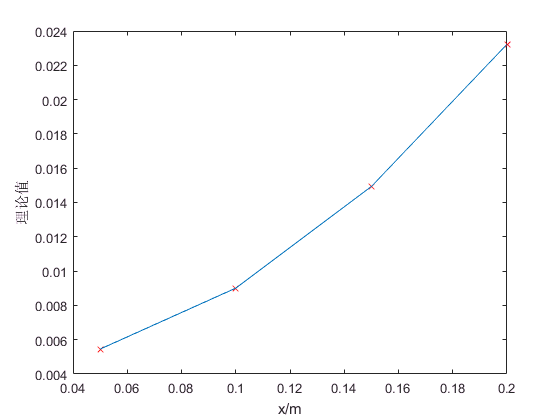

xlabel('x/m');
ylabel('理论值')
plot(x,I_t,'-');

cent =  abs(I_r-I_t)./I_t;
display(cent);

cent =    0.002086136797772
   0.005658516241214
   0.002478179406534
   0.005463576045918